# Normalize linescan data.

Input: multiple .csv files created using the ManualLineScan.ijm ImageJ macro

Output: same .csv file with the n ormalized data appened

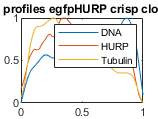

close all
clear all

filenames = uigetfile("*.csv","MultiSelect","on");
% opts = delimitedTextImportOptions("NumVariables", 5);
% 
% % Specify range and delimiter
% opts.DataLines = [2, Inf];
% opts.Delimiter = "\t";
% 
% % Specify column names and types
% opts.VariableNames = ["VarName1", "XCord", "Value1", "Value2", "Value3"];
% opts.VariableTypes = ["double", "double", "double", "double", "double"];
% 
% % Specify file level properties
% opts.ExtraColumnsRule = "ignore";
% opts.EmptyLineRule = "read";


for f = 1:length(filenames)

    currentFile = filenames{f};
    % Import the data
    data = readtable(currentFile);
    
    % start Normalization
    data.X_CordNorm = (data.X_Cord - min(data.X_Cord)) / (max(data.X_Cord) - min(data.X_Cord));
    data.Value1Norm = (data.Value1 - min(data.Value1)) / (max(data.Value1) - min(data.Value1));
    data.Value2Norm = (data.Value2 - min(data.Value2)) / (max(data.Value2) - min(data.Value2));
    data.Value3Norm = (data.Value3 - min(data.Value3)) / (max(data.Value3) - min(data.Value3));
    plot(data.X_CordNorm,data.Value1Norm);
    hold on;
    plot(data.X_CordNorm,data.Value2Norm);
    plot(data.X_CordNorm,data.Value3Norm);
    hold off
    legend('DNA','HURP','Tubulin');
    title('Plot profiles egfpHURP crisp clone11')
    writetable(data,currentFile);
    saveas(gcf,[currentFile(1:end-4),'_normalized.png']);

    
end 